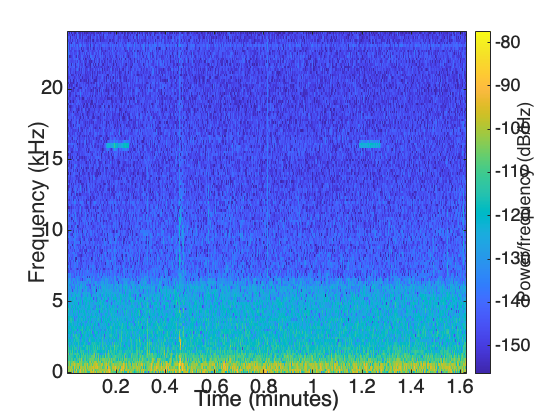

close all;
filename = '/Users/prerna/Documents/spatial_audio/data/mic3.WAV';

[y, fs]= audioread(filename);

figure
one=y(:,1); 
spectrogram(one, 256, [], [], fs, 'yaxis');


figure
two=y(:,2); 
spectrogram(two, 256, [], [], fs, 'yaxis');

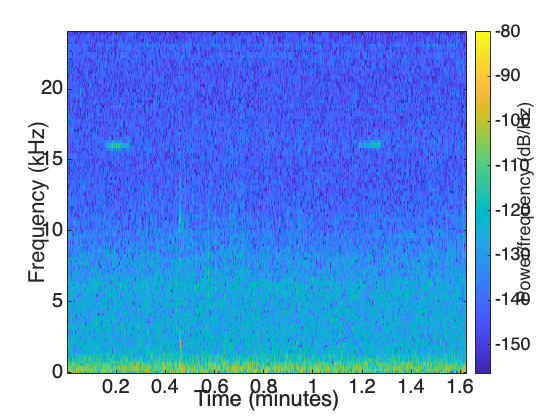


figure
three=y(:,3); 
spectrogram(three, 256, [], [], fs, 'yaxis');

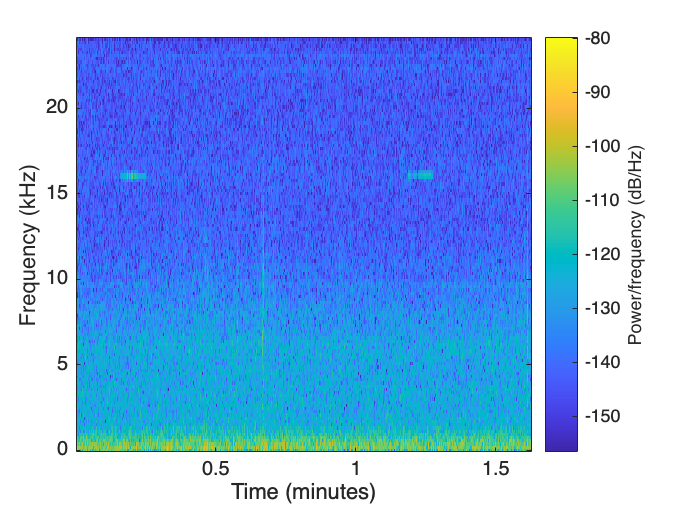


figure
four=y(:,4); 
spectrogram(four, 256, [], [], fs, 'yaxis');

% Sampling frequency
fs = 48000; % Replace with the actual sampling frequency of your recordings

% Generate a 16 kHz tone
tone_freq = 16000;
tone_duration = 5; % seconds
t = 0:1/fs:tone_duration;
sync_tone = sin(2 * pi * tone_freq * t);

% Load recorded signals (replace 'mic1.wav', 'mic2.wav', 'mic3.wav' with your actual file names)
mic1_signal = audioread('mic1.wav');
mic2_signal = audioread('mic2.wav');
mic3_signal = audioread('mic3.wav');

% Cross-correlation to find time delay
[correlation12, lag12] = xcorr(mic1_signal(:,1), mic2_signal(:,1));
[correlation13, lag13] = xcorr(mic1_signal(:,1), mic3_signal(:,1));
[correlation23, lag23] = xcorr(mic2_signal(:,1), mic3_signal(:,1));

% Find the lag with maximum correlation
[max_corr12, idx12] = max(abs(correlation12));
[max_corr13, idx13] = max(abs(correlation13));
[max_corr23, idx23] = max(abs(correlation23));

% Calculate time delays
delay12 = lag12(idx12) / fs;
delay13 = lag13(idx13) / fs;
delay23 = lag23(idx23) / fs;

% Display time delays
fprintf('Time delay between mic1 and mic2: %.5f seconds\n', delay12);

Time delay between mic1 and mic2: 4.32442 seconds


fprintf('Time delay between mic1 and mic3: %.5f seconds\n', delay13);

Time delay between mic1 and mic3: 7.69204 seconds


fprintf('Time delay between mic2 and mic3: %.5f seconds\n', delay23);

Time delay between mic2 and mic3: 3.25958 seconds


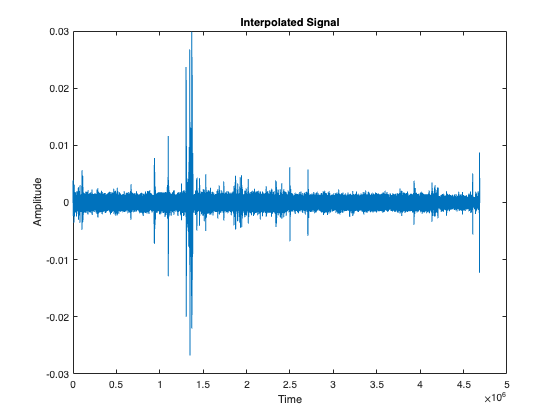

% Step 1: Define the parameters

% Number of microphones
M = 3;

% Order of Ambisonics
P = 4; % You can change this according to your needs

triangle_side = 6;

% Constants for the attenuation function
volume_threshold = 0.9;
volume_range = 0.9;
hoa_threshold = 0.9;
hoa_range = 1.3;

% Define the attenuation coefficient function a_p(d_m)
l = @(d) volume_threshold * (1 - volume_range * d);
k_p = @(d) hoa_threshold * (1 - hoa_range * d);

a_p = @(d) 10^((l(d) + k_p(d)) / 20);

% Step 2: Load your ambisonic signals y_m_p(n) from WAV files
% Replace this with your actual data loading code
path_to_files = '/Users/prerna/Documents/spatial_audio/data/';
file_names = {'mic1.wav', 'mic2.wav', 'mic3.wav'}; % Adjust with your file names

% Initialize an array to store ambisonic signals
y_m_p = zeros(M, P, 1); % Assuming each WAV file has the same number of samples

for m = 1:M
    % Read the WAV file
    [y, fs] = audioread(fullfile(path_to_files, file_names{m}));
    
    % Take the first 4 channels (assuming each mic produces 4 channels)
    y_m_p(m, :, 1:size(y, 1)) = y(:, 1:P)';
end

% Step 3: Implement the interpolation algorithm

% Number of samples
N = size(y_m_p, 3);

% Initialize the interpolated signal
x_p = zeros(1, N);


% Interpolation point coordinates (you need to specify the interpolation point)
interp_point = [triangle_side / 2, (triangle_side * sqrt(3)) / 6]; % Replace with the actual coordinates

% Loop over time samples
for n = 1:N
    % Loop over Ambisonic components
    for p = 1:P
        % Compute the attenuation coefficient for each microphone
        for m = 1:M
            % Replace this line with your actual distance calculation
            d_m = compute_distance(interp_point, m, triangle_side); % You need to implement compute_distance function
            % Update the interpolated signal using the distance attenuation formula
            x_p(n) = x_p(n) + a_p(d_m) * y_m_p(m, p, n);
        end
    end
end

% Step 4: Plot
% Replace this with your visualization code based on the requirements of your application
time_axis = 1:N;
figure;
plot(time_axis, x_p);
title('Interpolated Signal');
xlabel('Time');
ylabel('Amplitude');

audiowrite('output_mat.wav',x_p,fs);

function distance = compute_distance(interp_point, mic_number, triangle_side)
    % Microphone positions in the equilateral triangle
    mic_positions = zeros(3, 2);
    mic_positions(1, :) = [0, 0];
    mic_positions(2, :) = [triangle_side, 0];
    mic_positions(3, :) = [triangle_side / 2, (triangle_side * sqrt(3)) / 2];
    
    % Euclidean distance between the interpolation point and the microphone
    distance = norm(interp_point - mic_positions(mic_number, :));
end
